A script to hold official figures for reports and the paper.

datadir = 'C:\sync\biomes\cellulose\optima\clean_version\data';


Fig 1: Time series of biomass based on parameters from literature.

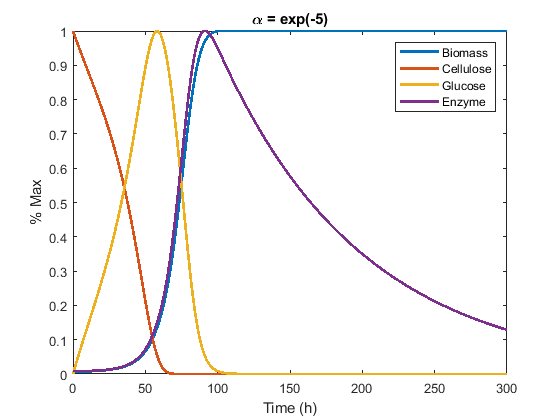

if ~exist('dat2_litParams','var')
    load([datadir '\dat2_litParams.mat']);
end
v = getOptVars();
km_estimate = v.km_cel;
kcat_estimate = v.kcat_cel;
km_estimate = 0.03;
kcat_estimate = 27;

subtab = dat2_litParams(dat2_litParams.kcat_cel == kcat_estimate,:);
subtab = subtab(subtab.km_cel == km_estimate,:);

row = subtab(dat2_litParams.alpha == exp(-5),:);
figure();
clear n;
n.biomass = row.biomass{1}/max(row.biomass{1});
n.cel = row.cellulose_amt{1}/max(row.cellulose_amt{1});
n.glc = row.glc_amt{1}/max(row.glc_amt{1});
n.enz = row.enzyme_amt{1}/max(row.enzyme_amt{1});
t = row.t{1};
plot(t,n.biomass,t,n.cel,t,n.glc,t,n.enz,'linewidth',2);
legend({'Biomass' 'Cellulose' 'Glucose' 'Enzyme'});
xlabel('Time (h)');
ylabel('% Max');
title(['\alpha = exp(' num2str(log(row.alpha(1))) ')']);

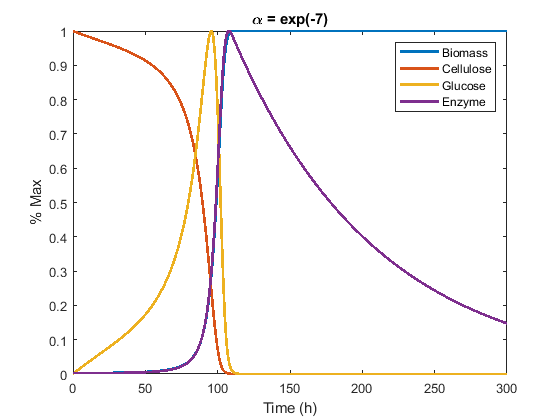


row = subtab(dat2_litParams.alpha == exp(-7),:);
figure();
n.biomass = row.biomass{1}/max(row.biomass{1});
n.cel = row.cellulose_amt{1}/max(row.cellulose_amt{1});
n.glc = row.glc_amt{1}/max(row.glc_amt{1});
n.enz = row.enzyme_amt{1}/max(row.enzyme_amt{1});
t = row.t{1};
plot(t,n.biomass,t,n.cel,t,n.glc,t,n.enz,'linewidth',2);
legend({'Biomass' 'Cellulose' 'Glucose' 'Enzyme'});
xlabel('Time (h)');
ylabel('% Max');
title(['\alpha = exp(' num2str(log(row.alpha(1))) ')']);

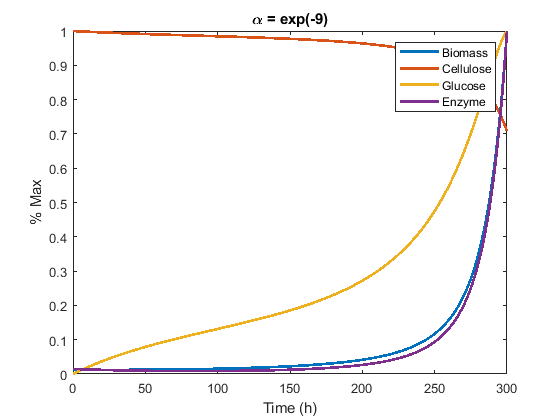


row = subtab(dat2_litParams.alpha == exp(-9),:);
figure();
n.biomass = row.biomass{1}/max(row.biomass{1});
n.cel = row.cellulose_amt{1}/max(row.cellulose_amt{1});
n.glc = row.glc_amt{1}/max(row.glc_amt{1});
n.enz = row.enzyme_amt{1}/max(row.enzyme_amt{1});
t = row.t{1};
plot(t,n.biomass,t,n.cel,t,n.glc,t,n.enz,'linewidth',2);
legend({'Biomass' 'Cellulose' 'Glucose' 'Enzyme'});
xlabel('Time (h)');
ylabel('% Max');
title(['\alpha = exp(' num2str(log(row.alpha(1))) ')']);

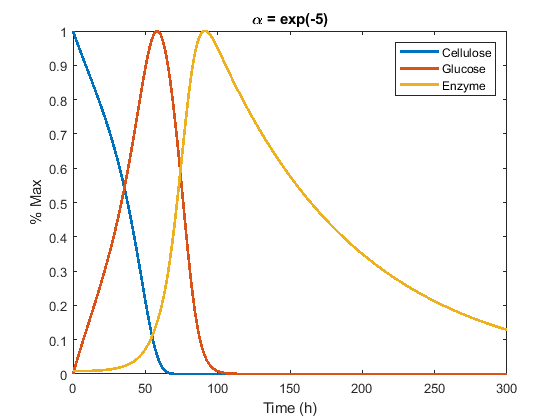


row = subtab(dat2_litParams.alpha == exp(-5),:);
figure();
n.cel = row.cellulose_amt{1}/max(row.cellulose_amt{1});
n.glc = row.glc_amt{1}/max(row.glc_amt{1});
n.enz = row.enzyme_amt{1}/max(row.enzyme_amt{1});
t = row.t{1};
plot(t,n.cel,t,n.glc,t,n.enz,'linewidth',2);
legend({'Cellulose' 'Glucose' 'Enzyme'});
xlabel('Time (h)');
ylabel('% Max');
title(['\alpha = exp(' num2str(log(row.alpha(1))) ')']);

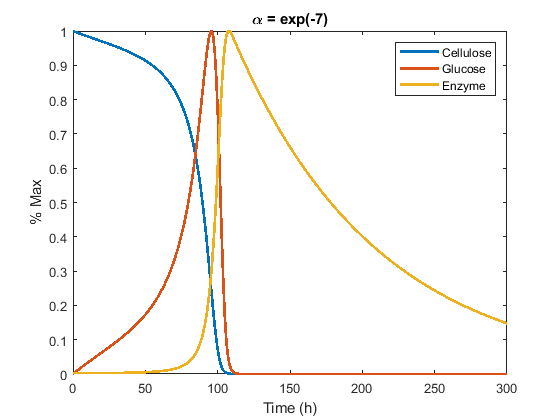

row = subtab(dat2_litParams.alpha == exp(-7),:);
figure();
n.cel = row.cellulose_amt{1}/max(row.cellulose_amt{1});
n.glc = row.glc_amt{1}/max(row.glc_amt{1});
n.enz = row.enzyme_amt{1}/max(row.enzyme_amt{1});
t = row.t{1};
plot(t,n.cel,t,n.glc,t,n.enz,'linewidth',2);
legend({'Cellulose' 'Glucose' 'Enzyme'});
xlabel('Time (h)');
ylabel('% Max');
title(['\alpha = exp(' num2str(log(row.alpha(1))) ')']);

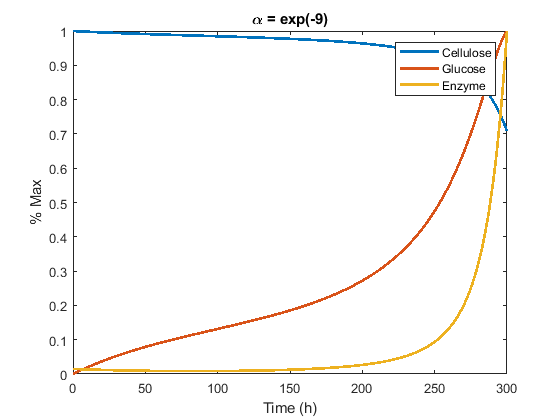

row = subtab(dat2_litParams.alpha == exp(-9),:);
figure();
n.cel = row.cellulose_amt{1}/max(row.cellulose_amt{1});
n.glc = row.glc_amt{1}/max(row.glc_amt{1});
n.enz = row.enzyme_amt{1}/max(row.enzyme_amt{1});
t = row.t{1};
plot(t,n.cel,t,n.glc,t,n.enz,'linewidth',2);
legend({'Cellulose' 'Glucose' 'Enzyme'});
xlabel('Time (h)');
ylabel('% Max');
title(['\alpha = exp(' num2str(log(row.alpha(1))) ')']);

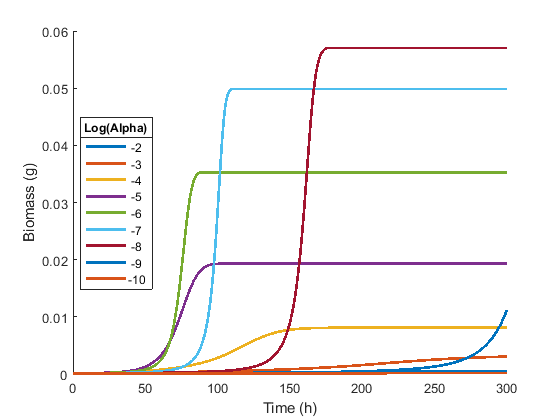

inttab = subtab(ismember(subtab.alpha,exp(-15:-1)),:);
figure();
hold on;
[nrows,~] = size(inttab);
for i = 1:nrows
    plot(t,inttab.biomass{i},'linewidth',2);
end
hold off;
xlabel('Time (h)');
ylabel('Biomass (g)');
leg = legend(num2str(log(inttab.alpha)),'location','best');
title(leg,'Log(Alpha)');

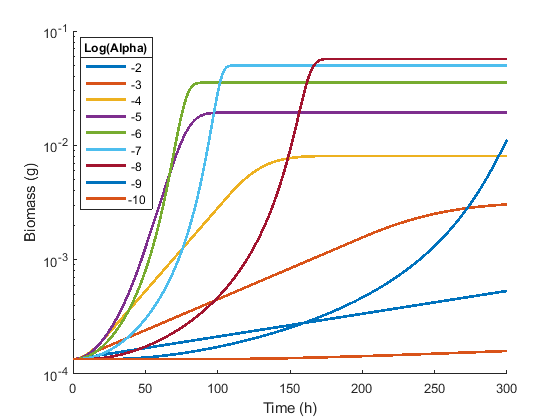


figure();
hold on;
[nrows,~] = size(inttab);
for i = 1:nrows
    plot(t,inttab.biomass{i},'linewidth',2);
end
hold off;
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca, 'YScale', 'log');
leg = legend(num2str(log(inttab.alpha)),'location','best');
title(leg,'Log(Alpha)');

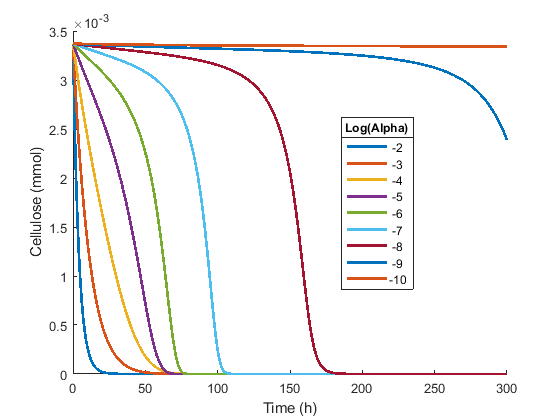

inttab = subtab(ismember(subtab.alpha,exp(-15:-1)),:);
figure();
hold on;
[nrows,~] = size(inttab);
for i = 1:nrows
    plot(t,inttab.cellulose_amt{i},'linewidth',2);
end
hold off;
xlabel('Time (h)');
ylabel('Cellulose (mmol)');
leg = legend(num2str(log(inttab.alpha)),'location','best');
title(leg,'Log(Alpha)');

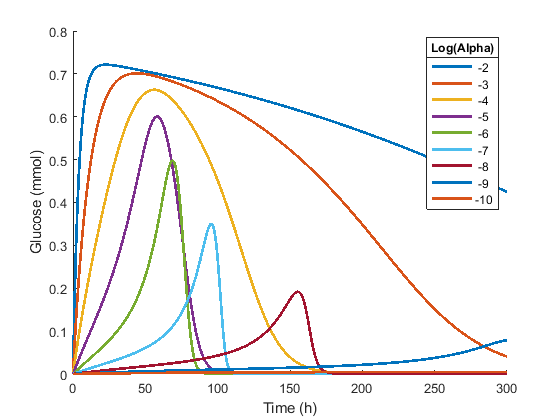


figure();
hold on;
[nrows,~] = size(inttab);
for i = 1:nrows
    plot(t,inttab.glc_amt{i},'linewidth',2);
end
hold off;
xlabel('Time (h)');
ylabel('Glucose (mmol)');
leg = legend(num2str(log(inttab.alpha)),'location','best');
title(leg,'Log(Alpha)');

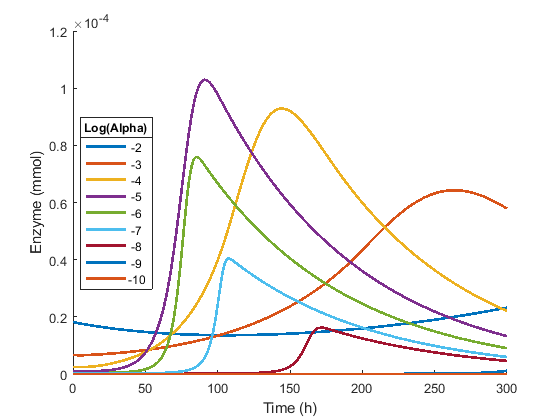


figure();
hold on;
[nrows,~] = size(inttab);
for i = 1:nrows
    plot(t,inttab.enzyme_amt{i},'linewidth',2);
end
hold off;
xlabel('Time (h)');
ylabel('Enzyme (mmol)');
leg = legend(num2str(log(inttab.alpha)),'location','best');
title(leg,'Log(Alpha)');

Fig 2: Comparison of in vitro biomass, prediction with params from literature, and fitted prediction

%Data prep
if ~exist('ivd','var')
    load([datadir '\ivd.mat']);
end
if ~exist('dat2','var')
    load([datadir '\dat2.mat']);
end
[nrows,~] = size(dat2);
for i = 1:nrows
    [rss,r2,V,K,rmse] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2.t{i},dat2.biomass{i},3,'log10');
    dat2.rmse(i) = rmse;
end
[nrows,~] = size(dat2_litParams);
for i = 1:nrows
    [rss,r2,V,K,rmse] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2_litParams.t{i},dat2_litParams.biomass{i},3,'log10');
    dat2_litParams.rmse(i) = rmse;
end
fitrow = dat2(dat2.rmse == min(dat2.rmse),:);
litrow = dat2_litParams(dat2_litParams.rmse == min(dat2_litParams.rmse),:);

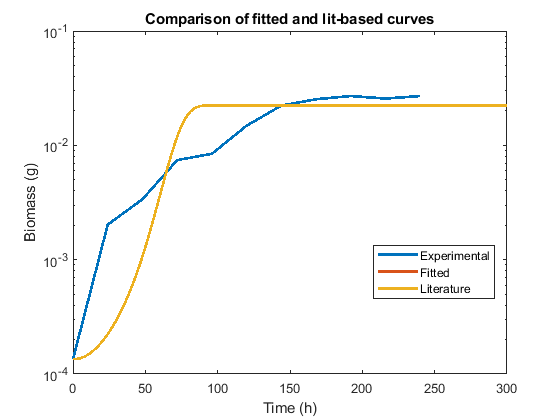

plot(ivd.denhaan.ctdat,ivd.denhaan.gdw,fitrow.t{1},fitrow.biomass{1},litrow.t{1},litrow.biomass{1},'linewidth',2);
legend({'Experimental' 'Fitted' 'Literature'},'location','best');
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca, 'YScale', 'log');
title('Comparison of fitted and lit-based curves');

['Fitted alpha = e^' num2str(log(fitrow.alpha(1)))] 

ans = 'Fitted alpha = e^-5.2'

['Fitted kcat = ' num2str(fitrow.kcat_cel(1))]

ans = 'Fitted kcat = 27'

['Fitted km = ' num2str(fitrow.km_cel(1))]

ans = 'Fitted km = 0.03'

['Fitted RMSE = ' num2str(fitrow.rmse(1))]

ans = 'Fitted RMSE = 0.22868'

['Lit alpha = e^' num2str(log(litrow.alpha(1)))]

ans = 'Lit alpha = e^-5.2'

['Lit kcat = ' num2str(litrow.kcat_cel(1))]

ans = 'Lit kcat = 27'

['Lit km = ' num2str(litrow.km_cel(1))]

ans = 'Lit km = 0.03'

['Lit RMSE = ' num2str(litrow.rmse(1))]

ans = 'Lit RMSE = 0.22868'